open_system("Articulated_arm_real_proportions");



test

path_simu = 'Articulated_arm_real_proportions';

set_param(path_simu, 'SolverType', 'Fixed-step');   % fixed-step solver
%before : set_param(path_simu, 'FixedStep', '0.001');         % time step in sec
set_param(path_simu, 'FixedStep', '0.001'); 
%before set_param(path_simu, 'StopTime', '100'); 
set_param(path_simu, 'StopTime', '10');             % simulate time

Sweep Value

K1vals = linspace(0.04, 0.08, 8);
K2vals = linspace(0.4,  0.8,  8);
K3vals = linspace(0.4,  0.8,  8);
delta_theta = linspace(0.5, 2.0, 8);


f_min = [2 2 2];
f_max = [20 20 20];
frac  = [0.8 0.8 0.8];

nbins = 10;
frac_thresh = 0.7;

counter = 0;

nSim = numel(K1vals)*numel(K2vals)*numel(K3vals)*numel(delta_theta);

% stockage FFT
FFT_store = cell(nSim,3);
F_store   = cell(nSim,3);


for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    set_param([path_simu '/Gain3'],  'Gain', num2str(K1vals(i1)));
    set_param([path_simu '/Gain9'],  'Gain', num2str(K1vals(i1)));
    set_param([path_simu '/Gain4'],  'Gain', num2str(K2vals(i2)));
    set_param([path_simu '/Gain10'], 'Gain', num2str(K2vals(i2)));
    set_param([path_simu '/Gain5'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/Gain8'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/delta_angle_deg_const'], 'Value', num2str(delta_theta(i4)));

    simOut = sim(path_simu);
    logsout = simOut.logsout;

    theta_1_signal = logsout.getElement('theta_1');
    theta_2_signal = logsout.getElement('theta_2');
    theta_3_signal = logsout.getElement('theta_3');

    theta_1_array_prev = squeeze(theta_1_signal.Values.Data);
    theta_2_array_prev = squeeze(theta_2_signal.Values.Data);
    theta_3_array_prev = squeeze(theta_3_signal.Values.Data);

    theta_1_array = theta_1_array_prev(:,1);
    theta_2_array = theta_2_array_prev(:,1);
    theta_3_array = theta_3_array_prev(:,1);

    if counter == 0
        time_array = theta_1_signal.Values.Time;
        N = numel(time_array);

        dt = time_array(2) - time_array(1);
        Fs = 1/dt;

        f = (0:N-1)*(Fs/N);
        f_pos = f(1:floor(N/2));
    end

    counter = counter + 1;

    signals = {theta_1_array, theta_2_array, theta_3_array};

    for t = 1:3

        signal = signals{t};

        signal = signal(:);

        Y = fft(signal);
        Y(1) = 0;

        P = abs(Y)/N;
        P = P(1:floor(N/2));

        idx = (f_pos >= f_min(t)) & (f_pos <= f_max(t));

        FFT_store{counter,t} = P(idx);
        F_store{counter,t}   = f_pos(idx);
    end

end
end
end
end

-------------------------
end = -0.039662
end = 0.000000
end = 0.275693
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.049113
end = 0.000000
end = 0.283457
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.059164
end = 0.000000
end = 0.290911
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.069591
end = 0.000000
end = 0.297969
-------------------------
best_next_thet

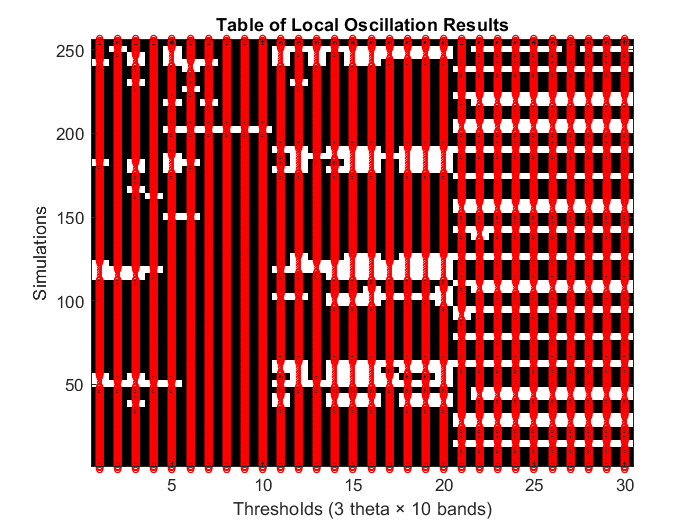

globalMax = zeros(3, nbins);

for s = 1:nSim
    for t = 1:3

        P_filt = FFT_store{s,t};
        f_filt = F_store{s,t};

        if isempty(P_filt)
            continue;
        end

        edges = linspace(f_min(t), f_max(t), nbins+1);

        for b = 1:nbins

            bin_idx = (f_filt >= edges(b)) & (f_filt < edges(b+1));
            bin_data = P_filt(bin_idx);

            if ~isempty(bin_data)
                globalMax(t,b) = max(globalMax(t,b), max(bin_data));
            end
        end
    end
end

globalThreshold = frac(:) .* globalMax;


oscTable = zeros(nSim,30);

for s = 1:nSim

    col = 1;

    for t = 1:3

        P_filt = FFT_store{s,t};
        f_filt = F_store{s,t};

        edges = linspace(f_min(t), f_max(t), nbins+1);

        for b = 1:nbins

            bin_idx = (f_filt >= edges(b)) & (f_filt < edges(b+1));
            bin_data = P_filt(bin_idx);

            if ~isempty(bin_data)

                th = globalThreshold(t,b);

                if any(abs(bin_data - th) < 1e-12 | bin_data > th)
                    oscTable(s,col) = 1;
                end
            end

            col = col + 1;
        end
    end
end


isOscillating = zeros(nSim,1);

for s = 1:nSim
    nbZeros = sum(oscTable(s,:) == 0);

    if nbZeros >= nbins * 3 * frac_thresh
        isOscillating(s) = 0;
    else
        isOscillating(s) = 1;
    end
end


figure;
imagesc(oscTable);

colormap(gray);
caxis([0 1]);

title('Table of Local Oscillation Results');
xlabel('Thresholds (3 theta × 10 bands)');
ylabel('Simulations');

axis tight;
set(gca, 'YDir','normal');


for i = 1:size(oscTable,1)
    for j = 1:size(oscTable,2)
        text(j,i,num2str(oscTable(i,j)), ...
            'HorizontalAlignment','center','Color','red');
    end
end



disp('Nombre simulations oscillantes :'); disp(sum(isOscillating));

Nombre simulations oscillantes :
   116



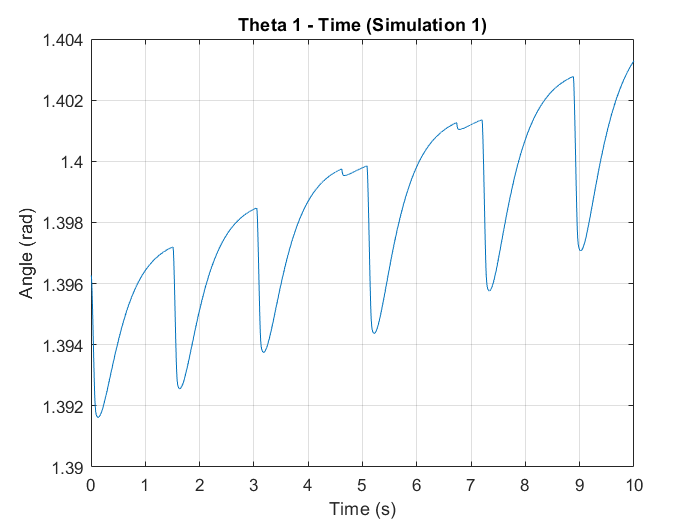


s = 1; 
theta1 = squeeze(theta_1(:,1,1,1,1));
theta2 = squeeze(theta_2(:,1,1,1,1));
theta3 = squeeze(theta_3(:,1,1,1,1));

figure;
plot(time_array, theta1);
title('Theta 1 - Time (Simulation 1)');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

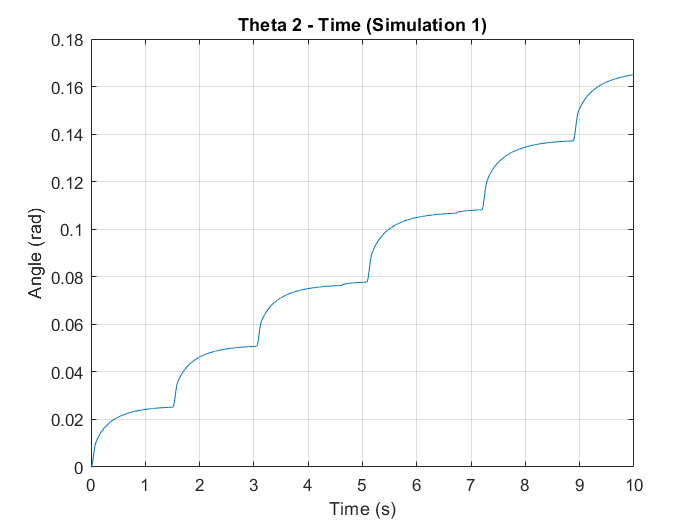


figure;
plot(time_array, theta2);
title('Theta 2 - Time (Simulation 1)');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

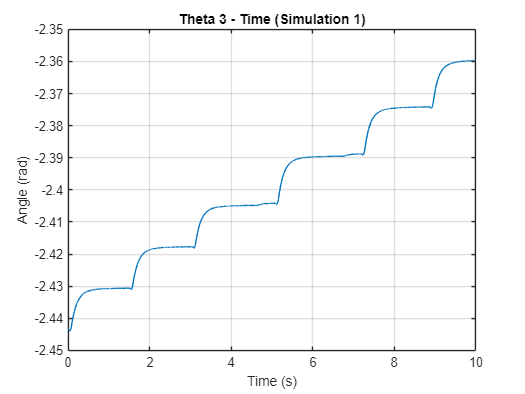


figure;
plot(time_array, theta3);
title('Theta 3 - Time (Simulation 1)');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

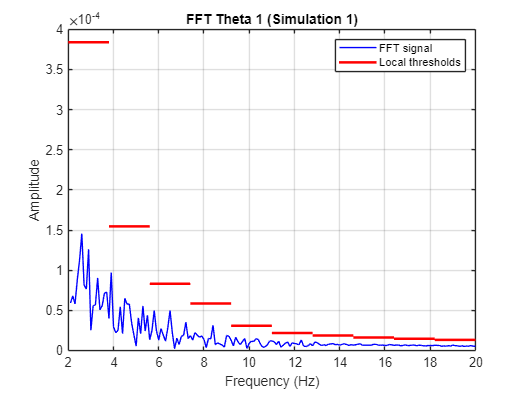

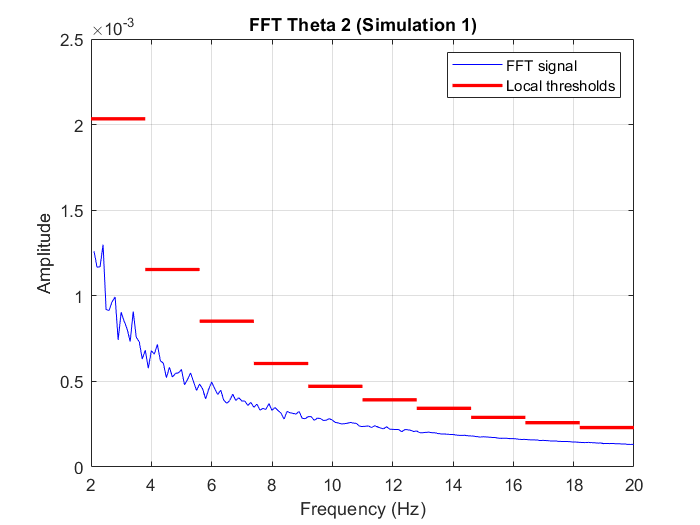

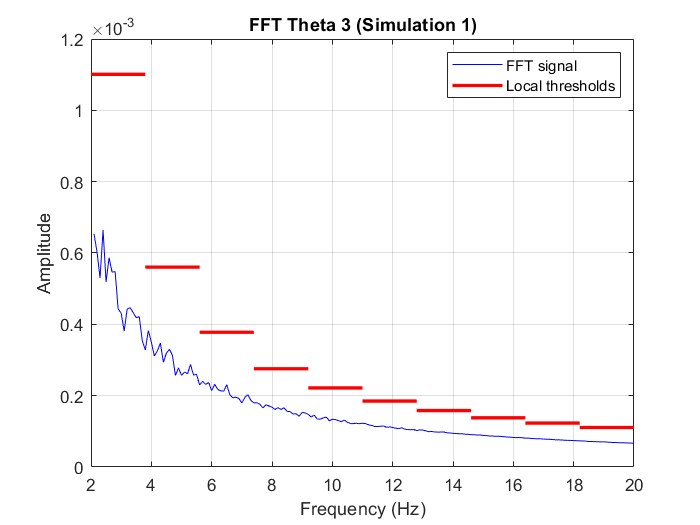


for t = 1:3
    
    P_filt = FFT_store{s,t};
    f_filt = F_store{s,t};

    figure;

    hFFT = plot(f_filt, P_filt, 'b'); hold on;
    
    title(['FFT Theta ', num2str(t), ' (Simulation 1)']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    edges = linspace(f_min(t), f_max(t), nbins+1);

    for b = 1:nbins
        th = globalThreshold(t,b);
        hTh = plot([edges(b) edges(b+1)], [th th], 'r', 'LineWidth', 2);
    end

    legend([hFFT, hTh], ...
        {'FFT signal', 'Local thresholds'}, ...
        'Location','northeast');

end





nb_oscillating_per_sim = sum(oscTable,2)

nb_oscillating_per_sim =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


disp(nb_oscillating_per_sim)

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
    10
    10
    10
    10
     0
     0
     0
     0
     0
     0
     0
     0
    10
    10
    10
    10
    10
    10
    10
    10
     0
     0
     0
     0
     8
     8
     8
     8
    16
    16
    16
    16
     9
     9
     9
     9
    15
    15
    15
    15
     8
     8
     8
     8
     8
     8
     8
     8
    19
    19
    19
    19
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
    10
    10
    10
    10
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1
    10
    10
    10
    10
     4
     4
     4
     4
     9
     9
     9
     9
    11
    11
    11
    11
    10
    10
    10
    10
    10
    10
    10
    10
    14
    14
    14
    14
    10
    10
    10
    10
    16
    16
    16
    16
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1
    10
    10
    10



disp(size(theta_1));

       10001           2           2           2           2



disp(size(theta_2));

       10001           2           2           2           2



disp(size(theta_3));

       10001           2           2           2           2



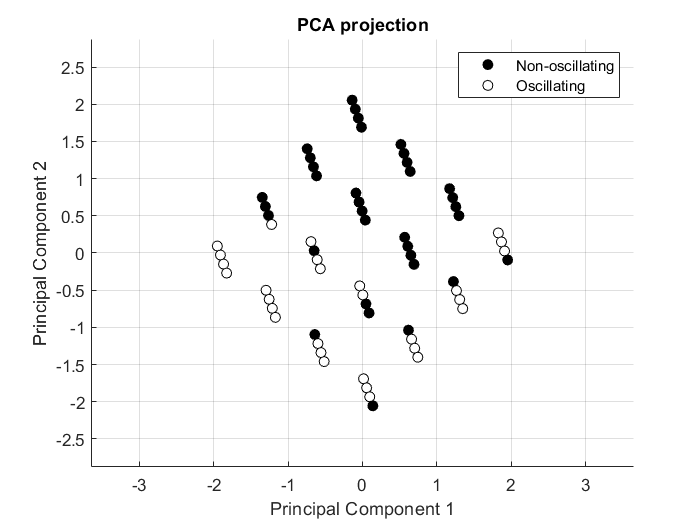


result4D = zeros(numel(K1vals), numel(K2vals), numel(K3vals), numel(delta_theta));

counter = 1;

for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    result4D(i1,i2,i3,i4) = isOscillating(counter);
    counter = counter + 1;

end
end
end
end


X = zeros(nSim,4);

counter = 1;

for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    X(counter, :) = [K1vals(i1), K2vals(i2), K3vals(i3), delta_theta(i4)];
    counter = counter + 1;

end
end
end
end



X_mean = mean(X);
X_std  = std(X);

X_norm = (X - X_mean) ./ X_std;


% matrice covariance
C = cov(X_norm);

% valeurs propres et vecteurs propres
[V, D] = eig(C);

% trier par ordre décroissant
[eigvals, idx] = sort(diag(D), 'descend');
V = V(:, idx);

% garder les 2 principales composantes
V2 = V(:,1:2);

% projection des données
X_pca = X_norm * V2;


figure;
hold on;

hStable = [];
hOsc = [];

for i = 1:nSim

    if isOscillating(i) == 0
        hStable = plot(X_pca(i,1), X_pca(i,2), 'ko', 'MarkerFaceColor', 'k');
    else
        hOsc = plot(X_pca(i,1), X_pca(i,2), 'ko', 'MarkerFaceColor', 'w');
    end

end

xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA projection');
grid on;

legend([hStable, hOsc], ...
    {'Non-oscillating', 'Oscillating'}, ...
    'Location','northeast');


x_min = min(X_pca(:,1));
x_max = max(X_pca(:,1));
y_min = min(X_pca(:,2));
y_max = max(X_pca(:,2));

% marge 20%: ça adapte les axes
dx = 0.2 * (x_max - x_min);
dy = 0.2 * (y_max - y_min);

xlim([x_min - dx, x_max + dx]);
ylim([y_min - dy, y_max + dy]);

axis equal;